clc; clearvars;
addpath(genpath("C:\Users\tely1\OneDrive\Matlab Onedrive\O3_Lidar\proc_functions"));
addpath(genpath("functions\"));

background_data_path = "bg_data.mat";

signal_dir = "C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\signal_data";

fds = read_lidar_datafiles2(signal_dir,"bin","ol");

n_shots = 1200;
f_sample = 40e6;
tau = 1/f_sample;
dz = physconst("LightSpeed") * tau / 2;

bg_bins = 7000:8000;

n_files = size(fds.Files,1);

bg_287 = NaN(n_files,1);
bg_299 = NaN(n_files,1);
dates = NaT(n_files,1);

if false==true
    parfor i = 1:n_files
        temp = read(fds);
        temp_data = temp.data;
        temp_config = temp.config;
    
        pc = scale_binary_pc(squeeze(temp_data(:,:,[1 2],2)), dz, n_shots);
        bg = mean(pc(bg_bins,:),1);
    
        bg_287(i) = bg(1) .* 1e6 * tau; % background counts per bin
        bg_299(i) = bg(2) .* 1e6 * tau;
    
        dates = temp.time(2); % using middle time of measurement
    end
else
    load(background_data_path)
end

bg_287_avg = mean(bg_287);
bg_299_avg = mean(bg_299);

tau = 1/40e6;
BW = 5e-9;
FOV = 1e-3;
Omega = FOV^2 * pi / 4;
A = pi *.2^2;
etaR = .1;

h = planckConstant;
c = physconst("LightSpeed");

L_287_avg = bg_287_avg ./ (etaR * A * Omega * BW * tau * (287e-9 / h / c));
L_299_avg = bg_299_avg ./ (etaR * A * Omega * BW * tau * (299e-9 / h / c));

save(background_data_path,"bg_287", "bg_299", "dates", "L_287_avg", "L_299_avg");

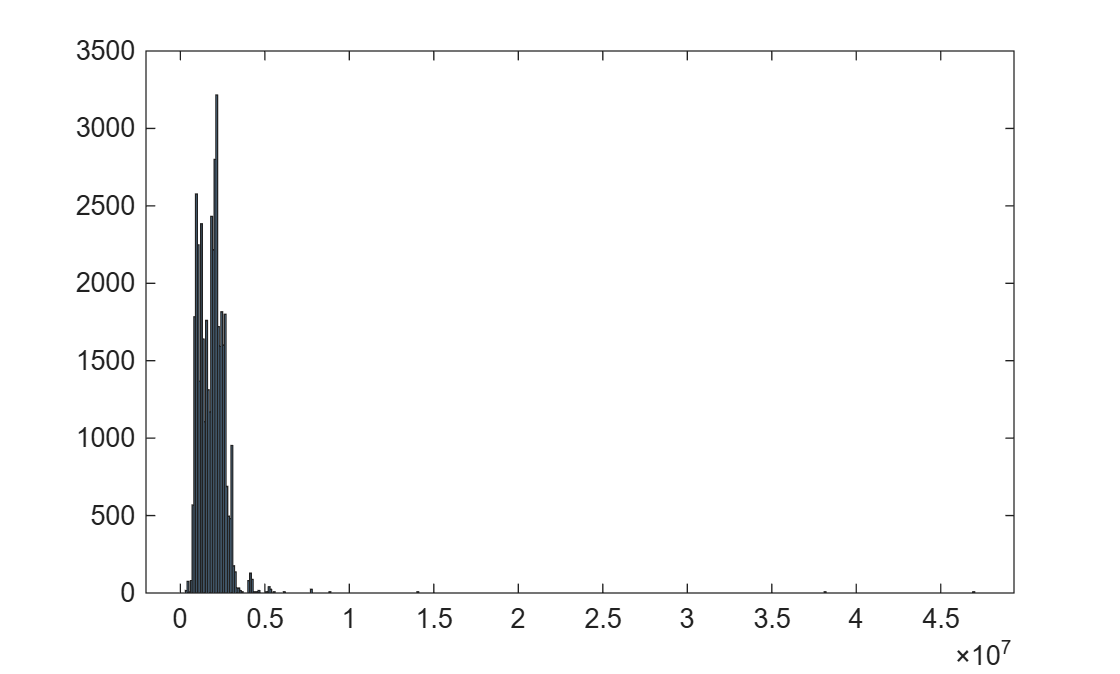

figure;
histogram(bg_287 ./ tau)

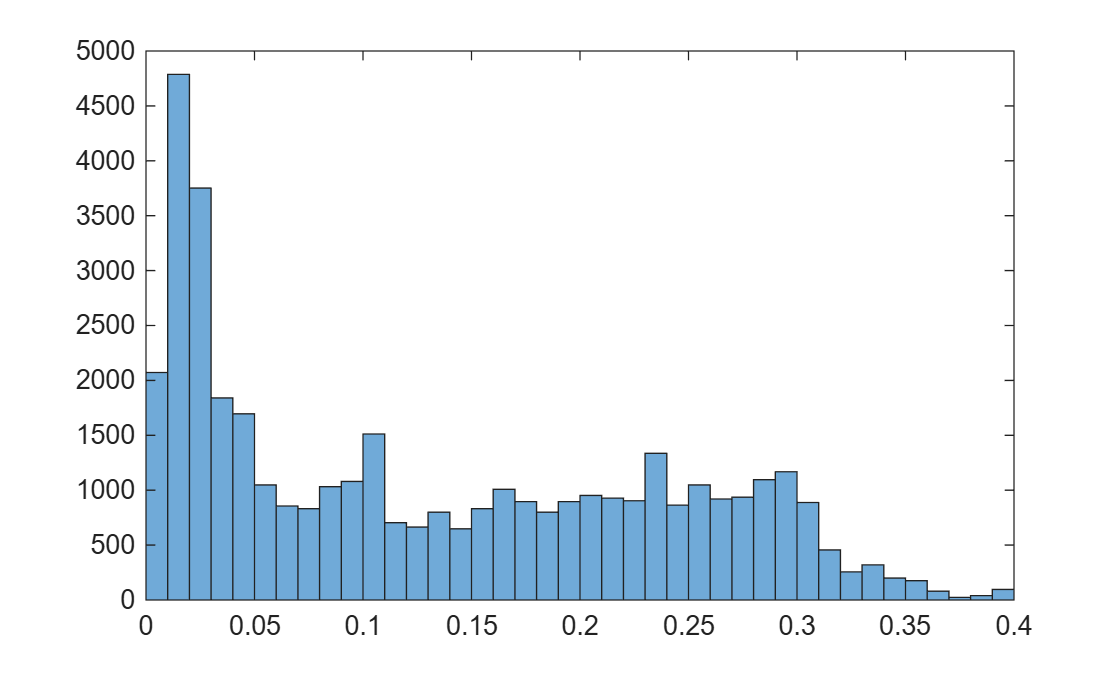

% xlim([0 .2])
figure;
histogram(bg_299)
xlim([0 .4])

function fds = read_lidar_datafiles2(folder_path,file_format,prefix)
    arguments
        folder_path string
        file_format string
        prefix string = "ol"
    end
    
    % create FDS of ozone lidar data-files
    switch file_format
        case "mat"
            fds = fileDatastore(folder_path, 'ReadFcn', @readTEMAT, 'FileExtensions','.mat');
    
        case "bin"
            dir_info = dir(fullfile(folder_path, "**"));
            filenames = string({dir_info.name});
            ol_ids = ~[dir_info().isdir] & startsWith(filenames,prefix);
    
            ol_files = dir_info(ol_ids);
            ol_paths = fullfile(string({ol_files.folder}), string({ol_files.name}));
            fds = fileDatastore(ol_paths,'ReadFcn',@readLicelBinary);
    
        case "txt"
            fds = fileDatastore(folder_path, 'ReadFcn', @readLicelASCII, 'FileExtensions','.txt');
    
    
        case "list"
            filename_list = folder_path;
            fds = fileDatastore(filename_list,'ReadFcn',@readLicelBinary);
    end
end